# Worksheet 3: HIV

#### Due Friday, October 23

This worksheet is likely to feel a bit different from the first two, because we're going to provide a little less scaffolding and leave you to do larger chunks of work at a time, especially in implementing the model.

As in Worksheets 1 and 2, there are three main parts (plus some reading questions at the beginning and reflection questions at the end), which we are expecting that you will be able to start in studio during our three class sessions this week, and comfortably finish as homework. You are welcome to work ahead, but you should plan to use the class time to collaborate with the other students at your studio table; on Monday we'll suggest some ways to ensure that these interactions contribute to everyone's learning.

### Learning Objectives

After completing this worksheet, you should be able to:

- Identify the main points of the Phillips (1996) paper, including its central modeling question, the answer obtained to this question, and the possible significance of this answer.

- Represent the model described the paper as a stock-and-flow diagram and fully specify it as a system of ordinary differential equations (including initial conditions and parameter values with appropriate units).

- Simulate the model using Euler's method and reproduce the key results of the paper.

- Create an equivalent implementation of the model using MATLAB's `ode45` solver and verify that it produces results that are consistent with Euler's method.HW 4HeaeHW 

- Identify the validation strategies employed by the author of the paper and assess their effectiveness.

## 1. Reading Questions

Please read Andrew N. Phillips (1996), "Reduction of HIV Concentration During Acute Infection: Independence from a Specific Immune Response," *Science* 271:497-499. Then answer the following questions.

(**Process suggestion:** Briefly discuss these questions at your studio table, and take some notes to capture your thinking. Flesh our your answers after class; a few sentences per question should suffice.)

1.1. What is the main question of the paper? What is the answer?

**Response:**

In an HIV infection, there is generally a surge of virus particles followed by a drastic decrease (of several orders of magnitude). This has traditionally been assumed to be the result of some HIV-specific immune response. The purpose of this study was to determine if it's possible to explain this phenomenon without an HIV-specific immune response. They discovered that simple population dynamics could be responsible for this behavior without any HIV-specific immune response being present.

1.2. Why is this answer interesting? Why might it have been considered important enough to publish in *Science*?

**Response:**

This result is significant because HIV's main effect is to supress the immune system, so understanding the immune system's reaction to it is important for understanding the disease. Additionally, since this result contradicts the previously-held scientific consensus, it is significant for moving the state-of-the-art in understanding HIV forward. 

1.3. What role does the model play in answering the question? What kind of work is it doing?

**Response:**

The model is used as a proof-of-cocept to illustrate that a HIV-specific immune response isn't required to obverve this sort of behavior. It doesn't prove that the immune response doesn't exist, but it does open the door to future studies on the existance (or lack thereof) of the immune response.

## 2. The Model

### As a System of Ordinary Differential Equations

Here are the four equations of the model:


$$\begin{array}{rcl}
\frac{dR}{dt} &=& \Gamma \tau - \mu R - \beta R V \\
\frac{dL}{dt} &=& p \beta R V - \mu L - \alpha L \\
\frac{dE}{dt} &=& (1-p) \beta R V + \alpha L - \delta E \\
\frac{dV}{dt} &=& \pi E - \sigma V
\end{array}$$


2.1. What are the 4 state variables? What are the 9 model parameters?

(Note that there seems to be a typo in Table 1; the parameter labeled with the Greek letter rho ($\rho$) is the same as the one labeled *p* in the text.)

**Response:**

*State Variables:*

- R: Activated, Uninfected CD4 Lymphocytes

- L: Latently Infected Cells

- E: Actively Infected Cells

- V: Free Virions

*Model Parameters:*

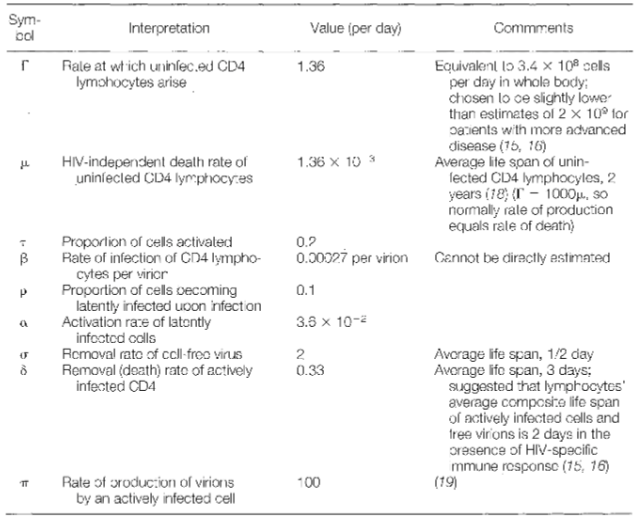

2.2. What are the units of each equation? For each equation, verify that the units are the same for each term.

**Response:**

All variables are counting numbers (ie. a number of things). Therefore, all rates of change are in terms of "things per day". This is why the only constant that has a "per <whatever>" unit is β, which is multiplied by not one but two of the state variables--therefore, it needs to have a "per whatever" to avoid ending up with a "whatever^2" in the output.

2.3. The parameter values are given in Table 1 of the paper. What are the initial values of the four state variables (stocks)?

(See Figure 1 and the text on page 497. Two of them are a little tricky! Note that Table 2 summarizes the results of the model for different values of $\alpha$, $\delta$, $\pi$, $\Gamma$, and $\beta$. You are welcome to explore these on your own, but for this worksheet we’ll stick with the values in Table 1.)

**Response:**

- V = 100

- E = 0

- L = 0

- R = 200 (since $1000\left(1-\tau \right)+R+L+E$is constant)

### As a Stock-and-Flow Diagram

2.4. Use the equations above to construct a stock-and-flow diagram for the model in the paper. Be sure to label it appropriately; bonus points for indicating the flows in a sufficiently precise way that someone could reconstruct the four equations from your diagram.

(Okay, there aren’t really bonus points in ModSim. Brownie points??)

**Response:**

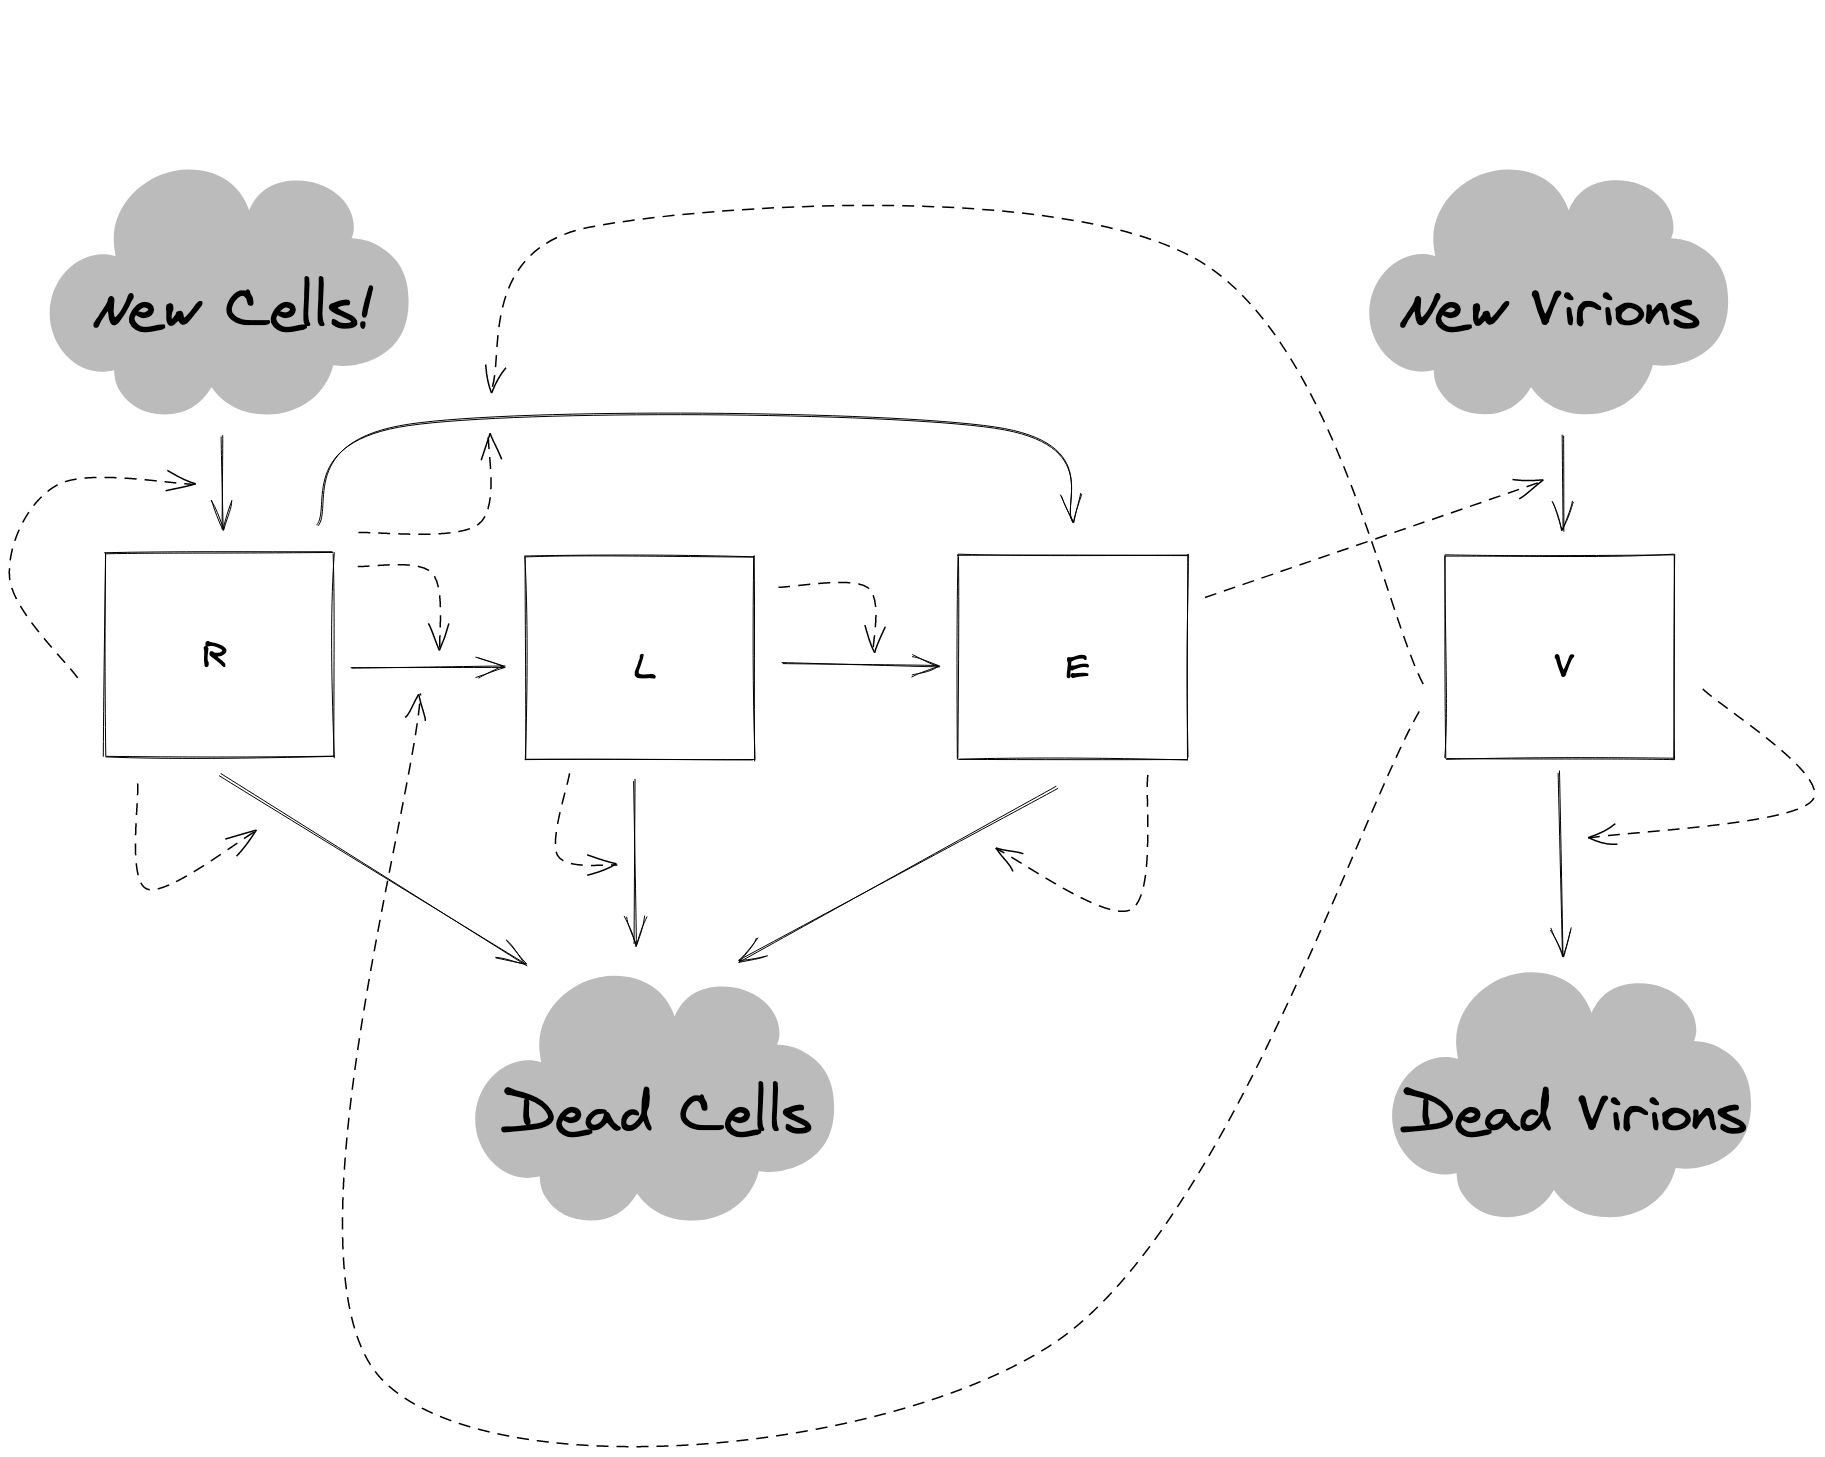

### Simulation Parameters

2.5. There are just a few more pieces of information you need in order to implement the HIV model in MATLAB — specifically, the start and end time, and the step length. What are the values of each of these parameters?

(See Figure 1 again.)

**Response:**

- Time step: per day

- Time range: 0 -> 120

### Fitting Parameters

2.6. In Worksheet 2 you fit two parameters: beta and gamma. For gamma you had direct measurements, while you had to adjust the value of beta to match model outputs to physical data. Among the parameters you found in 2.5, which are more like gamma (direct measurements), and which are more like beta (require model adjustment to fit)?

**Response:**

In order:

- Gamma: Measured

- Mu: Measured

- Tau: Adjustment

- Beta: Adjustment

- Rho: Adjustment

- Alpha: Adjustment

- Sigma: Measured

- Delta: Measured

- Pi: Adjustment

***PROGRESS CHECK: We are expecting you to complete the questions above before class on Wednesday. If you get stuck, we suggest consulting a CA or someone at your studio table before you come to class; this will help everyone benefit from collaborating during the studio time.***

## 3. Simulation by Euler's Method

You are now ready to implement the HIV model in MATLAB and simulate it by numerically solving the above system of ODEs using Euler's method.

You should do this in a separate `.m` file. We suggest creating a MATLAB function called `hiv_euler()`, similar to the `haddock_euler()` function we showed you on Day 16 and the `lotka_euler()` function we will show you on Day 18. Be sure to include an explicit time step (`dt`) in your implemenation of Euler's method.

3.1. Call your simulation function below, and do pplot of the results. Convince yourself that the results are consistent with the ones shown in the paper (but don't try to reproduce the graphs in Figure 1 quite yet).

**Response:**

% Run the Model
global dt; % KLUDGE
dt = 80 / (24 * 60);

tStart = 0;
tEnd = 120;

[T, M] = hiv_euler(@hiv_error, dt, [tStart, tEnd], [100, 0, 0, 200]);

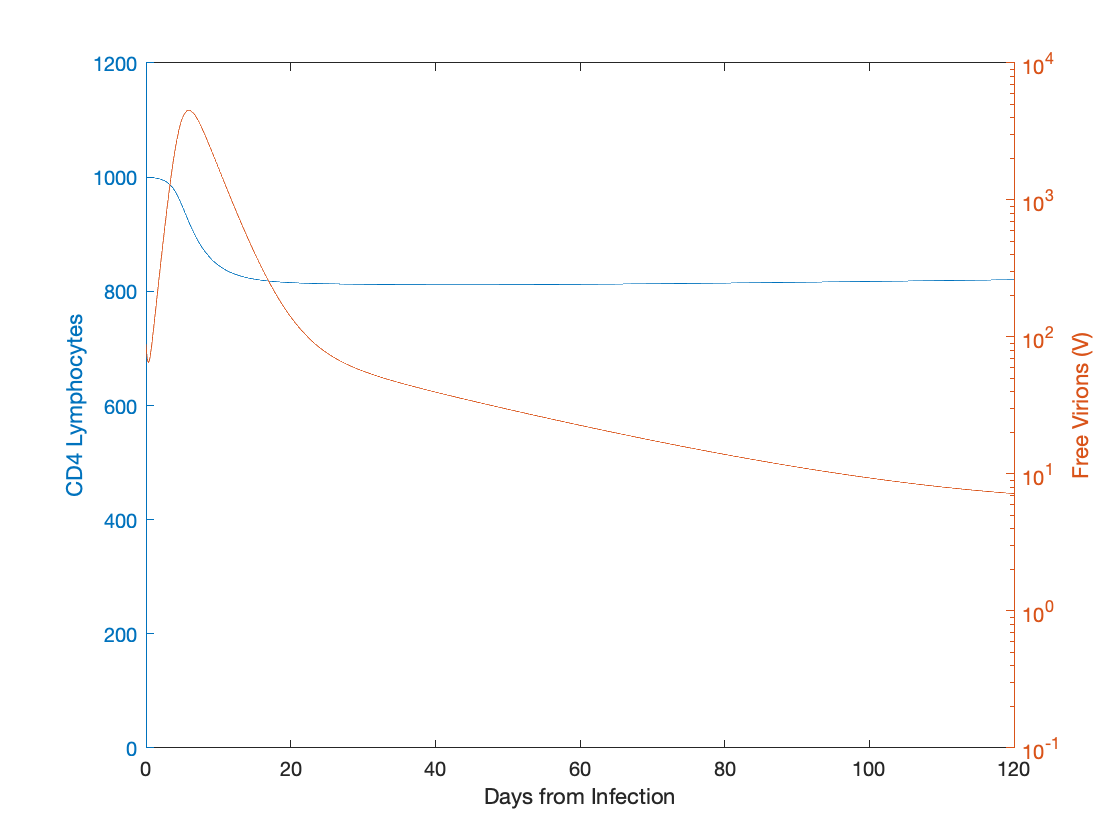

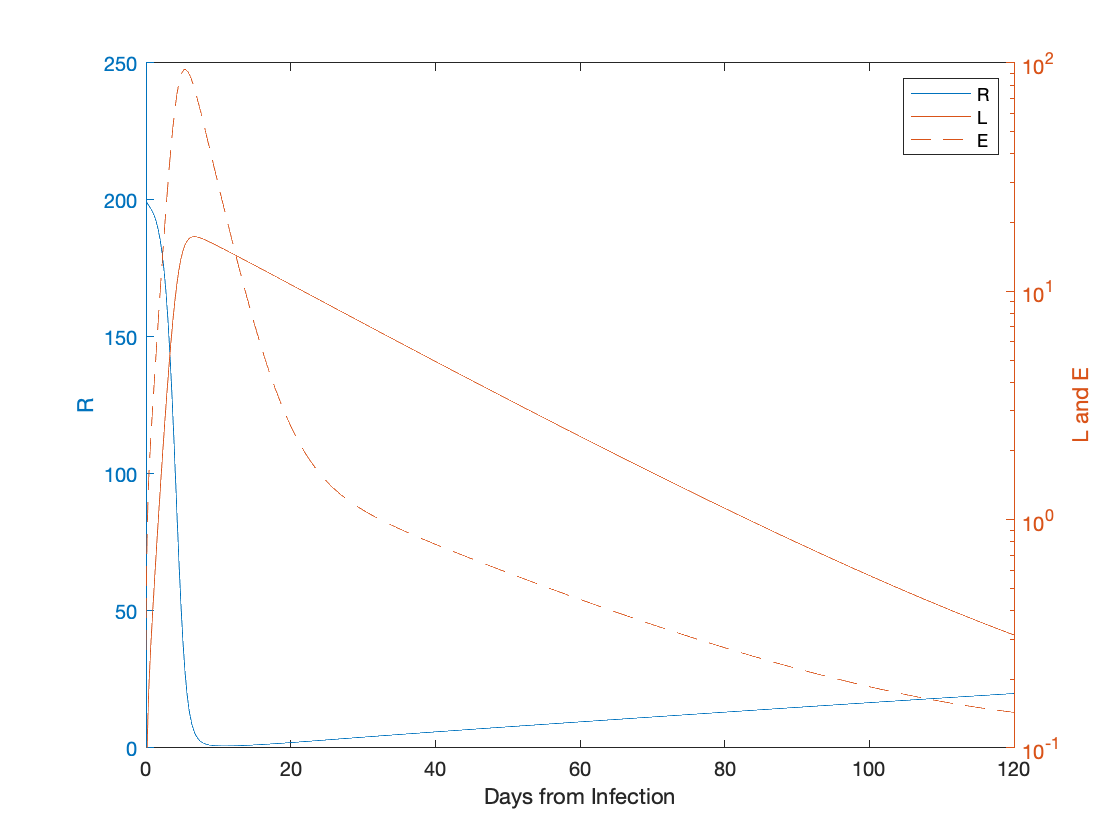

% Plot
plotModel(T, M)

3.2. Try playing around with the time step (`dt`). How short does it need to be in order to produce smooth-looking curves? What happens if you set it to 1 day (or forget to include an explicit time step)? Why?

**Response:**

I'm getting ~0.1 as the minimum required timestep. If you set it to 1, the entire thing explodes.

***PROGRESS CHECK: We are expecting you to complete the questions above before class on Friday. Once again, if you get stuck, we suggest consulting a CA or someone at your studio table before you come to class.***

## 4. Simulation by `ode45`

Now that you've implemented the model using Euler's method, we'd like you to convert it to use MATLAB's built-in `ode45` solver. For Projects 2 and 3, you will be welcome to use either method; this exercise ensures that you know how to do both.

We suggest that you create another separate `.m` file, perhaps called `hiv_ode45()`. Feel free to use your Euler function as a starting point, and adapt any of the example code we've provided.

4.1. Call your simulation function below, and do a simple plot of the results. Convince yourself that the results are consistent with the ones you obtained from Euler's method.

**Response:**

[T, M] = ode45(@hiv_error, [tStart, tEnd], [100, 0, 0, 200]);

4.2. Now try to reproduce the graphs in Figure 1. Note that *V*, *L*, and *E* are plotted on log scales. Also note that there is no explicit stock of total CD4 lymphocytes; you'll have to construct it yourself.

(It's fine if you plot every stock on its own graph. If you want to stretch your MATLAB plotting skills, try using the [`yyaxis`](https://www.mathworks.com/help/matlab/ref/yyaxis.html) command to create a second y-axis with a different scale. You may need to consult the documentation and/or your favorite search engine.)

**Response:**

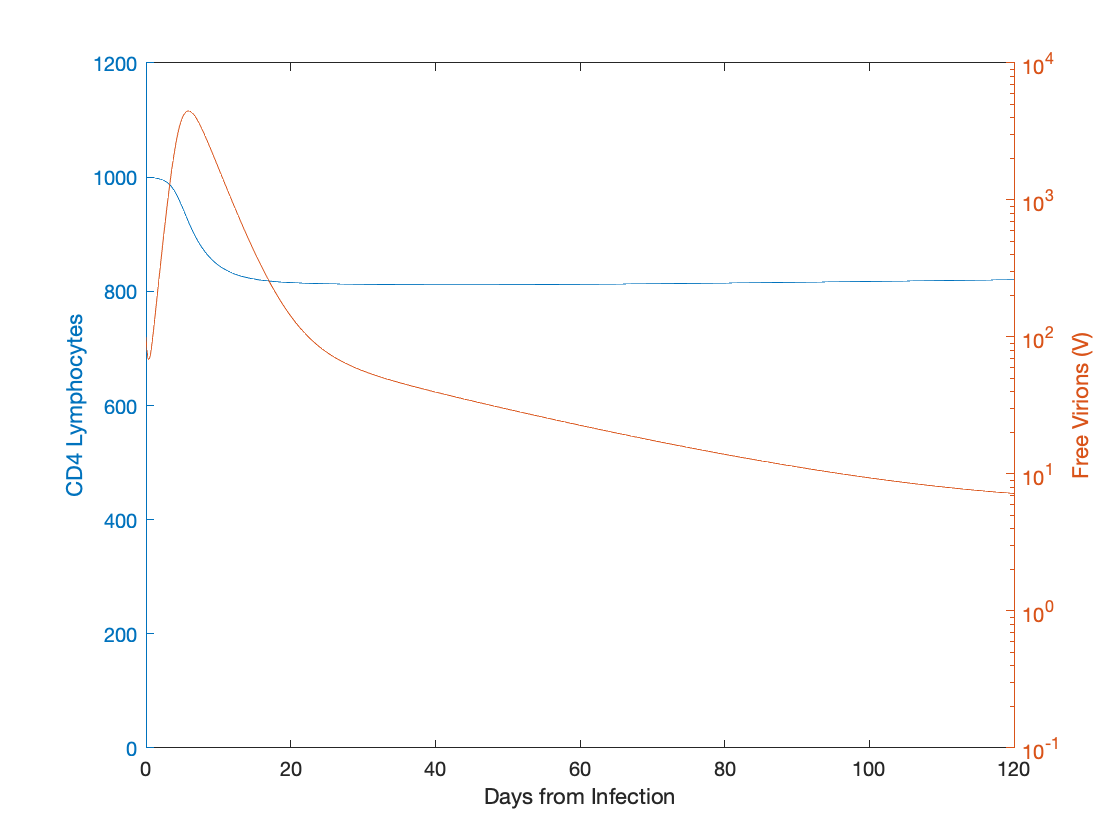

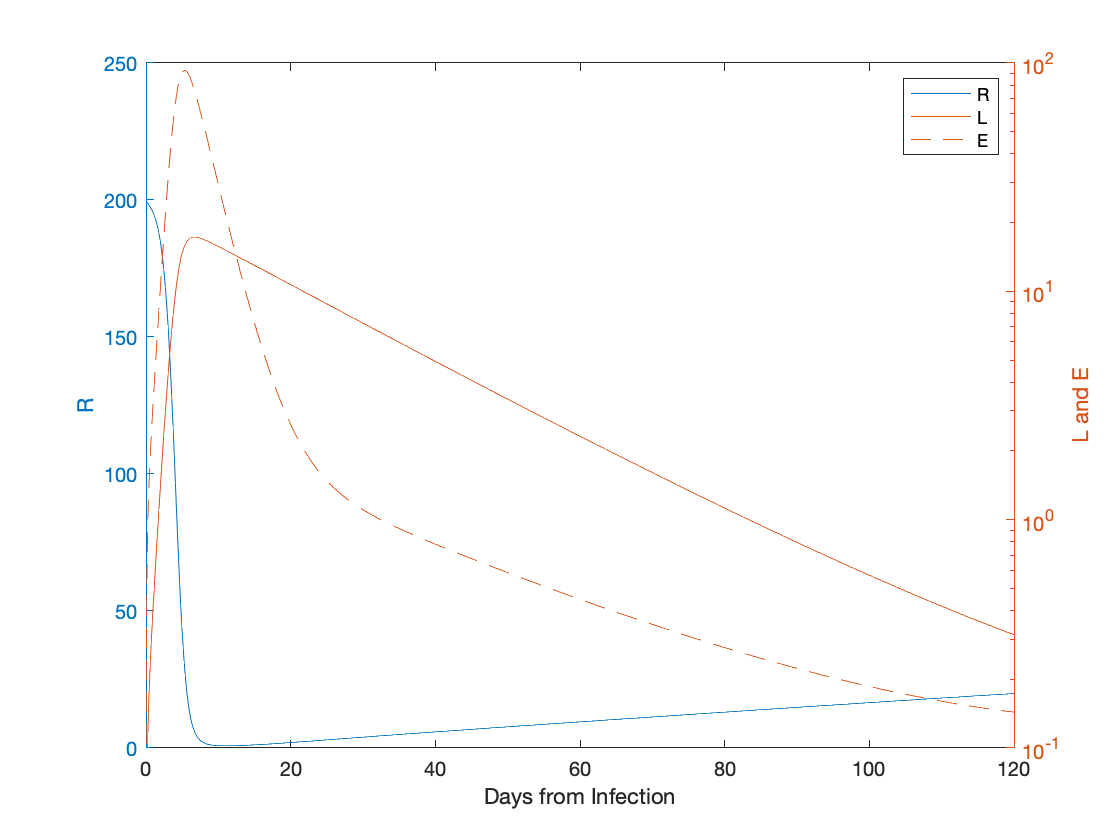

plotModel(T, M)

4.3. What validation strategies did the author of the paper employ? How effective do you think they were? To the extent they succeeded, how do they build your confidence in the main result? To the extent they fell short, what more do you think the author could or should have done?

**Response:**

The paper mostly did validation my comparing itself to existing models in the field. I think this was a so-so method of validation. In general, I think that validating something through logic and previously-validated models is generally acceptable. However, it would have been stronger if they had actually validated it against real data.

## 5. Reflection Questions

The purpose of this final section is to give you an opportunity to reflect on your experience in completing the worksheet. This information may be helpful for your studio instructor, but it is mainly intended to be helpful to you.

5.1. What was the most challenging part of this worksheet for you? Did you get stuck at any point along the way? If so, what strategies did you employ to get unstuck, and how did they work?

**Response:**

Throughout this worksheet, I continually hit the frusturating nature of MATLAB. In particular, the ambiguity as to the difference between column vectors, row vectors, and matricies. I kept running into issues with vectors that were the wrong direction, and I didn't want to just randomly transpose things to get them to fit.

5.2. How did the "virtual studio table" experience work for you this time around? Was anything notably better or worse than the first two worksheets? If so, why do you think things went differently?

**Response:**

I think it went fine, and roughly the same as previous worksheets--I'm not really sure anything was meaningfully different this time.

function plotModel(T, M)
    figure; clf;
    
    yyaxis left;
    tau = 0.2; % KLUDGE: Keep in sync with tau in hiv_euler
    plot(T, M(:, 4) + M(:, 3) + M(:, 2) + (1000 * (1 - tau)));
    ylim([0 1200]);
    ylabel("CD4 Lymphocytes")
    
    yyaxis right;
    semilogy(T, M(:, 1));
    ylim([0.1 10000]);
    ylabel("Free Virions (V)");
    xlabel("Days from Infection");
    
    figure; clf;
    
    yyaxis left;
    lineR = plot(T, M(:, 4));
    ylim([0 250]);
    ylabel("R");
    
    yyaxis right; 
    lineL = semilogy(T, M(:, 3));
    hold on;
    lineE = semilogy(T, M(:, 2));
    ylim([0.1 100])
    ylabel("L and E");
    legend([lineR, lineL, lineE], ["R", "L", "E"])
    xlabel("Days from Infection");
end